## **Osservazione: chi sostiene l'esame con il proprio computer il giorno precedente l'esame deve rimuovere la versione attualmente installata di FSDA ed installare l'ultima versione**

# ESERCIZIO I

Caricare in memoria il dataset di FSDA denominato D1 tramite l'ìstruzione load D1.mat Calcolare la matrice di correlazione in formato table tra le variabili del dataset e la matrice dei diagrammi di dispersione. Inserire il valore del coefficiente di correlazione lineare in ogni pannello della matrice dei diagrammi di dispersione e cololarlo in rosso oppure in nero a seconda della sua significatività

disp("Esercizio I: SOLUZIONE")

Esercizio I: SOLUZIONE


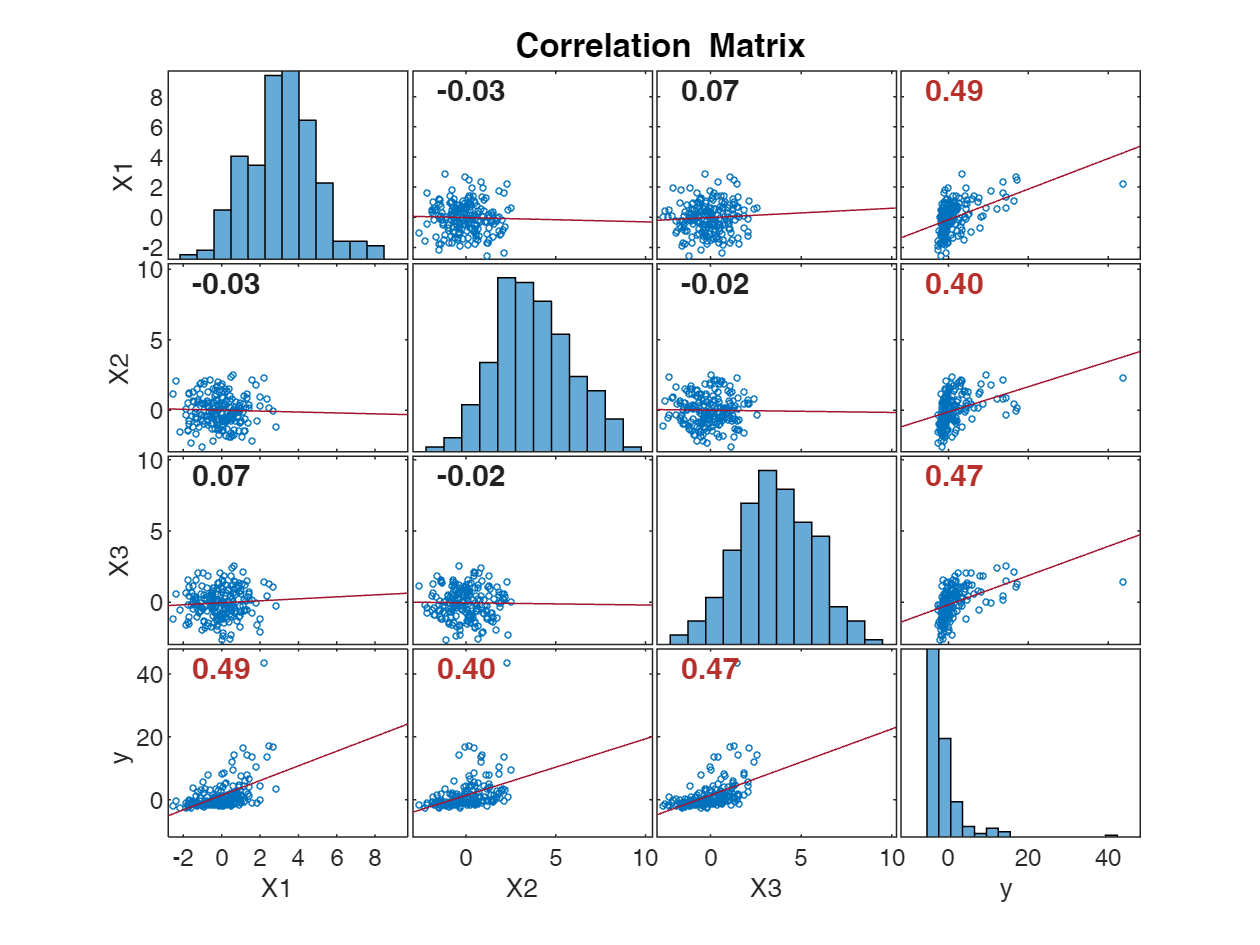


load D1.mat
% v. p. 319 del libro
[Rt,Pvalt]=corrplot(D1,"TestR","on");

disp('Matrice di correlazione in formato table')

Matrice di correlazione in formato table


disp(Rt)

             X1          X2           X3           y   
          ________    _________    _________    _______

    X1           1      -0.0302     0.065421    0.48694
    X2     -0.0302            1    -0.015579    0.40094
    X3    0.065421    -0.015579            1    0.46524
    y      0.48694      0.40094      0.46524          1



disp('Matrice dei p-values del test di assenza di correlazione')

Matrice dei p-values del test di assenza di correlazione


disp(Pvalt)

              X1            X2           X3            y     
          __________    __________    _________    __________

    X1             1       0.67119      0.35738    2.6447e-13
    X2       0.67119             1      0.82669    4.0213e-09
    X3       0.35738       0.82669            1     3.895e-12
    y     2.6447e-13    4.0213e-09    3.895e-12             1





% Commento: le variabili esplicative X1, X2 e X3 sono tra loro incorrelate
% I p-values del test di assenza di correlazione sono tutti molto grandi.
% Accetto l'ipotesti nulla di assenza di correlazione tra le variabili X1,
% X2 e X3
% La relazione tra y e le tre variabili esplicative è intorno a 0.40 --
% 0.50 ed è significativa


## ESERCIZIO II

Caricare in memoria il dataset di FSDA citiesItaly. Trovare tutte le città il cui nome finisce per "no". Mostrare nella Command Window il valore aggiunto e l'indicatore di disoccupazione per questi record.

% V. gli esercizi di riepilogo del capitolo 1 nel sito di Giappichelli
disp("Esercizio II: SOLUZIONE")

Esercizio II: SOLUZIONE


load citiesItaly.mat
rownam=citiesItaly.Properties.RowNames;
sel=endsWith(rownam,'no');
disp('Valore aggiunto ed indicatore di disoccupazione per le province il cui nome termina con "no"')

Valore aggiunto ed indicatore di disoccupazione per le province il cui nome termina con "no"


disp(citiesItaly(sel,["addedval" "unemploy"]))

                addedval    unemploy
                ________    ________

    Torino       23583        7.86  
    Verbano      19773        4.62  
    Milano       31050        5.22  
    Bolzano      26534        2.08  
    Belluno      19592        3.17  
    Livorno      17565        8.42  
    Avellino     12399       17.15  
    Salerno      12515       16.46  
    Oristano     12336       21.44  



## ESERCIZIO III

Creare (tramite ciclo for oppure moltiplicazione matriciale) la matrice che segue

disp("Esercizio III: SOLUZIONE")

Esercizio III: SOLUZIONE



% La prima colonna è la sequenza 8, 14, ..., 38
% La seconda colonna è la sequenza precedente moltitplicata per 2
% La terza colonna è la sequenza precedente moltitplicata per 3
% ...
% La decima colonna è la sequenza precedente moltitplicata per 10
X=(8:6:38)'*(1:10);
disp('Soluzione tramite moltiplicazione matriciale')

Soluzione tramite moltiplicazione matriciale


disp(X)

     8    16    24    32    40    48    56    64    72    80
    14    28    42    56    70    84    98   112   126   140
    20    40    60    80   100   120   140   160   180   200
    26    52    78   104   130   156   182   208   234   260
    32    64    96   128   160   192   224   256   288   320
    38    76   114   152   190   228   266   304   342   380



% In alternativa
% X=(4:3:19)'*(2:2:20);

% In alternativa
disp('Soluzione tramite ciclo for')

Soluzione tramite ciclo for


Primacolonna=(8:6:38)';
X=zeros(6,10);
for j=1:10
    X(:,j)=Primacolonna*j;
end
disp(X)

     8    16    24    32    40    48    56    64    72    80
    14    28    42    56    70    84    98   112   126   140
    20    40    60    80   100   120   140   160   180   200
    26    52    78   104   130   156   182   208   234   260
    32    64    96   128   160   192   224   256   288   320
    38    76   114   152   190   228   266   304   342   380



## Esercizio IV

Importare i dati della serie storica dei valori del tasso di cambio presenti nel file cambio.xlsx in formato table. Denominare questa table con le prime 3 lettere del proprio cognome. Il file cambio.xlsx si trova in [http://www.riani.it/cambio.xlsx](http://www.riani.it/cambio.xlsx)

Assegnare alle due colonne delle table i nomi «date» e «tasso» e poi convertire la table in timetable (assegnare alla timetable il nome Yt)

Calcolare la media del tasso di cambio per ogni anno prima utilizzando la funzione pivot poi senza utilizzare la funzione pivot 

Rappresentare graficamente l'andamento della serie storica annuale delle medie del tasso di cambio tramite la funzione stackedplot. Estrarre i record della timetable Yt che vanno dal 2 di dicembre 2018 al 21 di dicembre 2018 (compreso). Mostrare questi record nella Command Window Calcolare la media del tasso di cambio dei record estratti al punto precedente escludendo i valori missing. Mostrare il valore della media nella Command Window 

disp("Esercizio IV: SOLUZIONE")

Esercizio IV: SOLUZIONE


RIA=webread('http://www.riani.it/cambio.xlsx');
RIA.Properties.VariableNames={'date' 'tasso'};
Yt=table2timetable(RIA);

% Media dei tassi di cambio tramite chiamata alla funzione pivot
Ytpiv=pivot(Yt,'Rows','date',RowsBinMethod='year',Method='mean',RowLabelPlacement='rownames');
disp('Medie dei tassi di cambio (calcolate tramite chiamata alla funzione pivot')

Medie dei tassi di cambio (calcolate tramite chiamata alla funzione pivot


disp(Ytpiv)

            mean_tasso
            __________

    2007      10.418  
    2008      10.224  
    2009      9.5277  
    2010      8.9712  
    2011       8.996  
    2012      8.1052  
    2013      8.1646  
    2014      8.1857  
    2015      6.9733  
    2016      7.3522  
    2017       7.629  
    2018      7.8081  
    2019      7.7355  
    2020      7.8747  
    2021      7.6625  



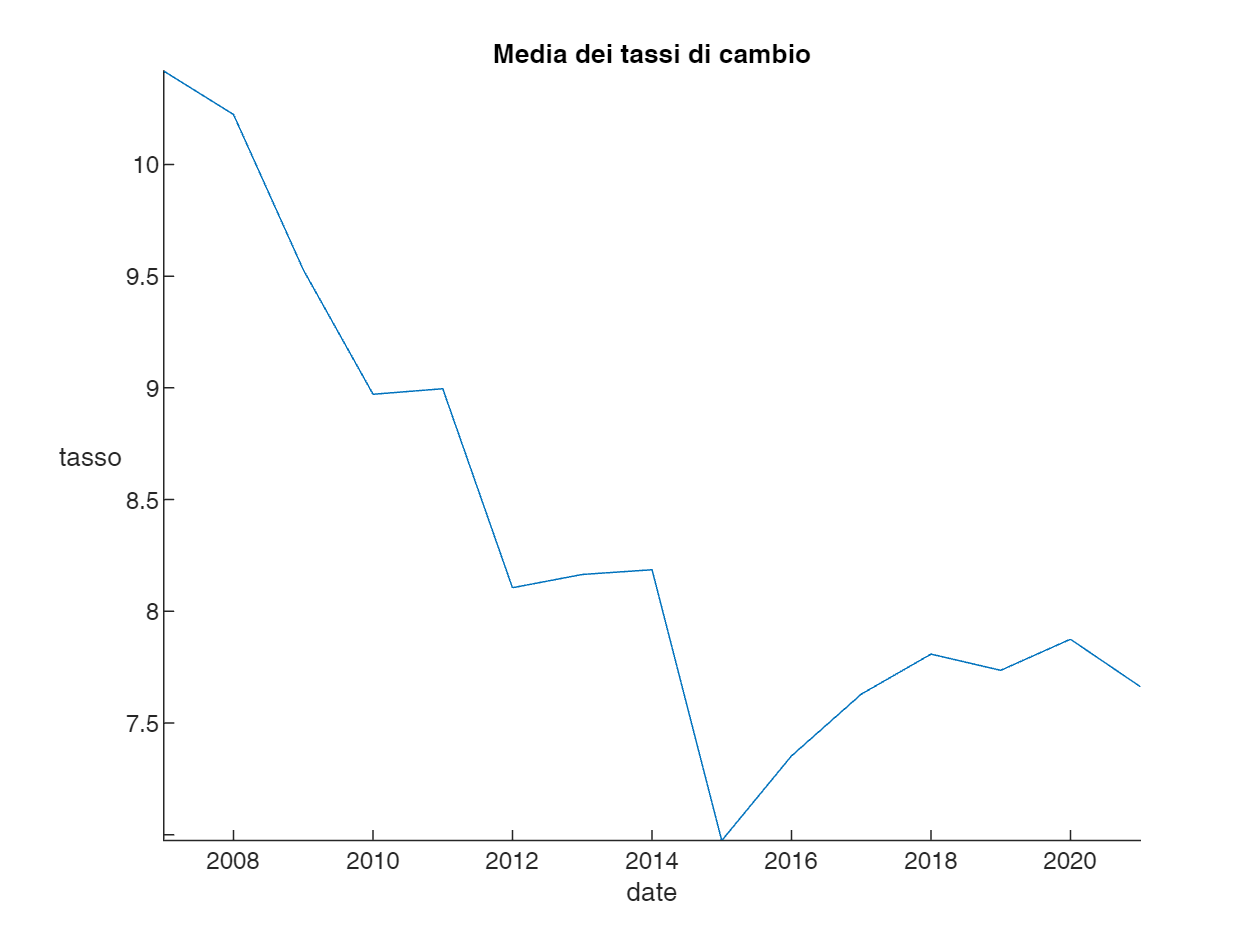

% Media dei tassi di cambio senza chiamata alla funzione pivot
Ytret=retime(Yt,"yearly","mean");

% Controllo uguaglianza delle due implementazioni

diff=max(abs(Ytpiv{:,1}-Ytret{:,1}))<1e-12;
assert(diff,"Le due implementazioni differiscono")


stackedplot(Ytret)
title('Media dei tassi di cambio')


%% Estrazione di dati
startdate=datetime(2018,12,2);
enddate=datetime(2018,12,22);

TR=timerange(startdate,enddate);
disp('Mostro il sottoperiodo che viene estratto')

Mostro il sottoperiodo che viene estratto


disp(TR)

	timetable timerange subscript:

		Select timetable rows with times in the half-open interval:
		[02-Dec-2018 00:00:00, 22-Dec-2018 00:00:00)

	See Select Times in Timetable.



Ytsel=Yt(TR,:);
MediaSenzaMis=mean(Ytsel,'omitmissing');
disp('Media dei valori del tax di cambio dal 2 di dicembre 2018 al 21 di dicembre 2018')

Media dei valori del tax di cambio dal 2 di dicembre 2018 al 21 di dicembre 2018


disp(MediaSenzaMis)

    tasso 
    ______

    7.8346



## Esercizio V

Utilizzando il file denominato TipoAcquistoProfessione.xlsx presente dentro il capitolo sull'analisi delle corrispondenze, costruire la tabella di contingenza tra le variabili Tipologia di acquisto e Professione. Effettuare l'analisi delle corrispondenze tra le due variabili. Utilizzando section separate discutere i seguenti aspetti

disp("Esercizio IV: SOLUZIONE")

Esercizio IV: SOLUZIONE


## OSSERVAZIONE: QUESTO ESERCIZIO ASSUME CHE IO MI TROVI NELLA CARTELLA matlabMfile (ossia la stessa cartella dove si trova il file di Errata Corrige del libro)

## Caricamento dati

Dato che il file si trova nella sottocartella capCorrispondenze deve specificare il percorso quando chiamto readtable

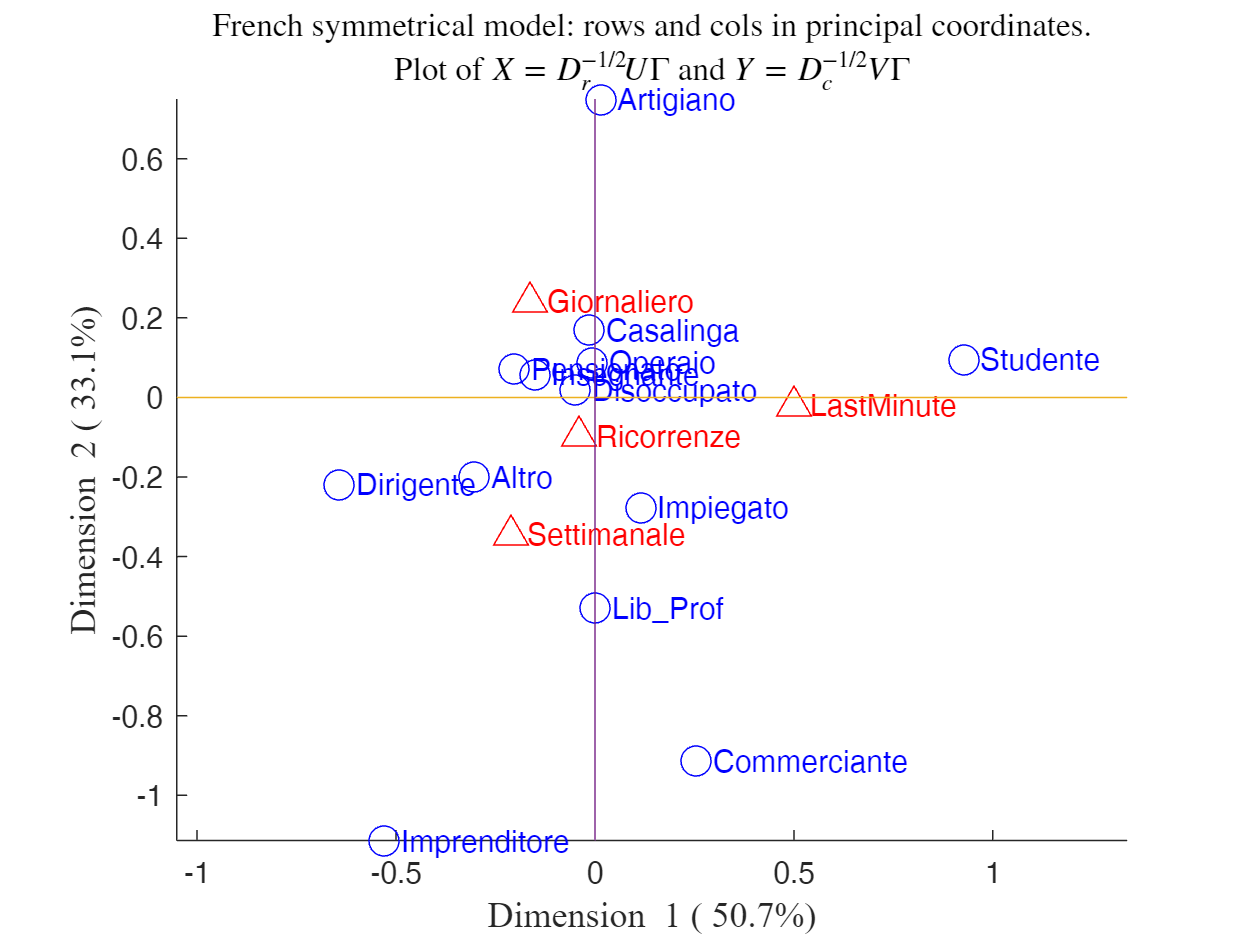

Summary
             Singular_value    Inertia     Accounted_for    Cumulative
             ______________    ________    _____________    __________

    dim_1       0.28988         0.08403       0.50665        0.50665  
    dim_2       0.23447        0.054977       0.33148        0.83812  
    dim_3       0.16385        0.026848       0.16188              1  

ROW POINTS
Results for dimension: 1
                      Scores      CntrbPnt2In    CntrbDim2In
                    __________    ___________    ___________

    Altro             -0.30246       0.01789        0.36689 
    Artigiano          0.01537    2.6396e-05     0.00038892 
    Casalinga   


X=readtable('capCorrispondenze/TipoAcquistoProfessione.xlsx','Range','B1:D427');

%% Analisi delle corrispondenze
out=CorAna(X(:,1:2),'datamatrix',true);


%% Commento sulla significatività della relazione tra le due variabili
disp("Valore del test Chi quadrato")

Valore del test Chi quadrato


disp(out.Chi2stat)

   70.6546



% Il valore  del test Chi quadrato deve essere confrontato con il valore
% critico di una distribuzione Chi2 con 36 gradi di libertà
disp("P-value del test Chi quadrato")

P-value del test Chi quadrato


pval=chi2cdf(out.Chi2stat,(out.I-1)*(out.J-1),'upper');
disp(pval)

   4.9109e-04



% Il p-value è molto basso (vicino a zero) ed ha un livello di
% significatività minore dell'1 per mille.
% Concludiamo che vi è un'associazione significativa tra i due fenomeni in
% esame




## Commento sulla spiegazione dell'inerzia

%% Commento sulla spiegazione dell'inerzia
disp(out.Summary)

             Singular_value    Inertia     Accounted_for    Cumulative
             ______________    ________    _____________    __________

    dim_1       0.28988         0.08403       0.50665        0.50665  
    dim_2       0.23447        0.054977       0.33148        0.83812  
    dim_3       0.16385        0.026848       0.16188              1  



% La percentuale di inerzia spiegata dalla prima componente è del 50.7 per
% cento mentre la percentuale dell'inerzia spiegata dalla seconda
% componente è pari al 33.1 per cento.
% La somma della percentuale di inerzia spiegata dalle prime due componenti
% latenti indica che nell'operazione di riduzione delle dimensioni si perde
% poca informazione. La percentuale cumulata della proporzione di inerzia
% spiegata con sole due dimensioni è pari all'83.8 per cento del valore
% massimo possibile.



## Commento al contributo dei punti riga alla spiegazione dell'inerzia tot

%% Commento al contributo dei punti riga alla spiegazione dell'inerzia tot
disp(out.OverviewRows(:,["CntrbPnt2In_1"  "CntrbPnt2In_2"]))

                    CntrbPnt2In_1    CntrbPnt2In_2
                    _____________    _____________

    Altro               0.01789         0.011868  
    Artigiano        2.6396e-05         0.096076  
    Casalinga        0.00039829          0.10066  
    Commerciante      0.0091331          0.17815  
    Dirigente           0.04591        0.0081245  
    Disoccupato      0.00032151       7.6506e-05  
    Impiegato          0.024024          0.20482  
    Imprenditore       0.023344          0.15893  
    Insegnante         0.012572        0.0028377  
    Lib_Prof         2.0096e-06          0.17879  
    Operaio          4.7294e-05         0.020078  
    Pensionato          0.14485         0.027936  
    S

% I punti riga che contribuiscono di più alla spiegazione dell'inerzia
% totale sono rappresentati dagli studenti per la dimensione 1 (seguiti dai
% pensionati). Per la dimensione 2 ve ne sono più di uno (impiegati,
% commercianti e liberi professionisti, seguiti dagli imprenditori), quasi
% della medesima importanza.

## Interpretazione delle due dimensioni latenti

%% Interpretazione delle due dimensioni latenti
% Le colonne dei contributi dei punti riga all'inerzia della dimensione, ci
% aiutano nel non sempre agevole compito di interpretare gli "assi
% dimensioni". Nell'esempio in questione si
% può affermare che la prima dimensione con riferimento ai profili riga
% è dominata dalle categorie non lavorative relative a studenti e
% pensionati (queste due categorie rappresentano i cosiddetti "punti dominanti".
% Per la seconda dimensione dei profili riga i punti dominanti sono
% relativi alle categorie degli impiegati dei liberi professionisti e dei
% commercianti.



## Contributi delle due dimensioni alla spiegazione dell'inerzia dei punti riga

%% Contributi delle due dimensioni alla spiegazione dell'inerzia dei punti riga
disp(out.OverviewRows(:,["CntrbDim2In_1"  "CntrbDim2In_2"]))

                    CntrbDim2In_1    CntrbDim2In_2
                    _____________    _____________

    Altro               0.36689          0.15924  
    Artigiano        0.00038892          0.92615  
    Casalinga         0.0042679          0.70569  
    Commerciante       0.061159          0.78048  
    Dirigente           0.69897         0.080927  
    Disoccupato        0.012897        0.0020078  
    Impiegato            0.1519          0.84724  
    Imprenditore         0.1347              0.6  
    Insegnante          0.18912         0.027929  
    Lib_Prof         1.6181e-05          0.94184  
    Operaio           0.0025056          0.69592  
    Pensionato          0.59263         0.074776  
    S

% Dall'analisi del contributo delle due dimensioni alla spiegazione
% dell'inerzia dei punti, è possibile determinare quali sono i punti
% profilo più sparsi. I contributi delle prime due dimensioni latenti
% all'inerzia dei punti riga rappresenta la quota di spiegazione dei
% singoli punti riga nel passaggio da uno spazio di dimensioni elevate ad
% uno spazio di dimensione 2. In questo caso si osserva che il profilo dei
% disoccupati è spiegato poco o per nulla, nella riduzione a due dimensioni
% dal momento che la somma dei contributi delle prime due dimensioni
% all'inerzia di tale punto riga è pari all’1.5 per cento del totale.
% Diversamente, il profilo degli impiegati è spiegato molto bene nella
% riduzione a due dimensioni, sebbene il totale del contributo (pari al
% 99.9 per cento circa) sia in larga parte dovuto alla seconda dimensione
% (84.7 per cento). Nelle applicazioni la somma dei primi due contributi
% della dimensione all'inerzia del punto generalmente non arriva quasi mai
% all'unità indicando che inevitabilmente il passaggio ad uno spazio di
% dimensioni ridotte fa perdere un po’ di informazione.



## Contributi dei punti colonna alla spiegazione dell'inerzia

%% Contributi dei punti colonna alla spiegazione dell'inerzia
disp(out.OverviewCols(:,["CntrbPnt2In_1"  "CntrbPnt2In_2"]))

                   CntrbPnt2In_1    CntrbPnt2In_2
                   _____________    _____________

    Giornaliero        0.12831          0.43975  
    Settimanale        0.13371           0.5441  
    LastMinute         0.73652        0.0018327  
    Ricorrenze       0.0014467         0.014322  



% I punti dominanti nella prima dimensione sono quelli relativi al tipo di
% acquisto dell'ultimo minuto, mentre per la seconda componente, vi è una
% quasi equa ripartizione di importanza per le tipologie d'acquisto
% giornaliero e settimanale.
% Questo suggerisce di interpretare la prima dimensione come indicatore
% associato ad un tipo di acquisto non pianificato, mentre la seconda
% dimensione è interpretabile come indicatore degli acquisti giornalieri e
% settimanali. Più precisamente, valori vicino a zero nella seconda
% dimensione latente sono associati agli acquisti last minute e ricorrenze.
% Al contrario, valori lontani zero nella seconda dimensione sono associati
% agli acquisti settimanali e giornalieri (in direzioni opposte).



## Contributi delle due dimensioni alla spiegazione dell'inerzia dei punti colonna

%% Contributi delle due dimensioni alla spiegazione dell'inerzia dei punti colonna
disp(out.OverviewCols(:,["CntrbDim2In_1"  "CntrbDim2In_2"]))

                   CntrbDim2In_1    CntrbDim2In_2
                   _____________    _____________

    Giornaliero        0.30459          0.68294  
    Settimanale        0.26135          0.69577  
    LastMinute         0.99186        0.0016147  
    Ricorrenze       0.0048502         0.031414  



% Analizzando il contributo percentuale della dimensione alla spiegazione
% dell'inerzia del punto, emerge che l'unica tipologia di acquisto che non
% viene spiegata nell'operazione di riduzione delle dimensioni è quella
% legata alle ricorrenze.



## Commento al grafico di analisi delle corrispondenze

%% Commento al grafico di analisi delle corrispondenze
% Le categorie, casalinghe, insegnanti, operai e pensionati e
% disoccupati, hanno profili di acquisto simili a quello medio, ossia si
% collocano molto vicini al punto (0,0) che rappresenta il baricentro
% (profilo medio). Tutte queste categorie si collocano nelle vicinanze
% del tipo di acquisto giornaliero (che evidentemente le caratterizza).
% Occorre sottolineare che la collocazione di una professione al profilo di
% acquisto legato ad eventi di ricorrenza è da interpretare con cautela,
% vista la poca rappresentatività di tale tipologia di acquisto. Le
% categorie professionali impiegati, liberi professionisti dirigenti ed
% altro sono più orientate ad effettuare un acquisto di tipo settimanale
% anziché giornaliero. 
% I profili degli imprenditori e (anche se in misura minore) i commercianti
% sono collocati nelle vicinanze degli acquisti settimanali mentre gli
% studenti sembrano preferire un acquisto dell'ultimo minuto. 



## Analisi tramite moonplot

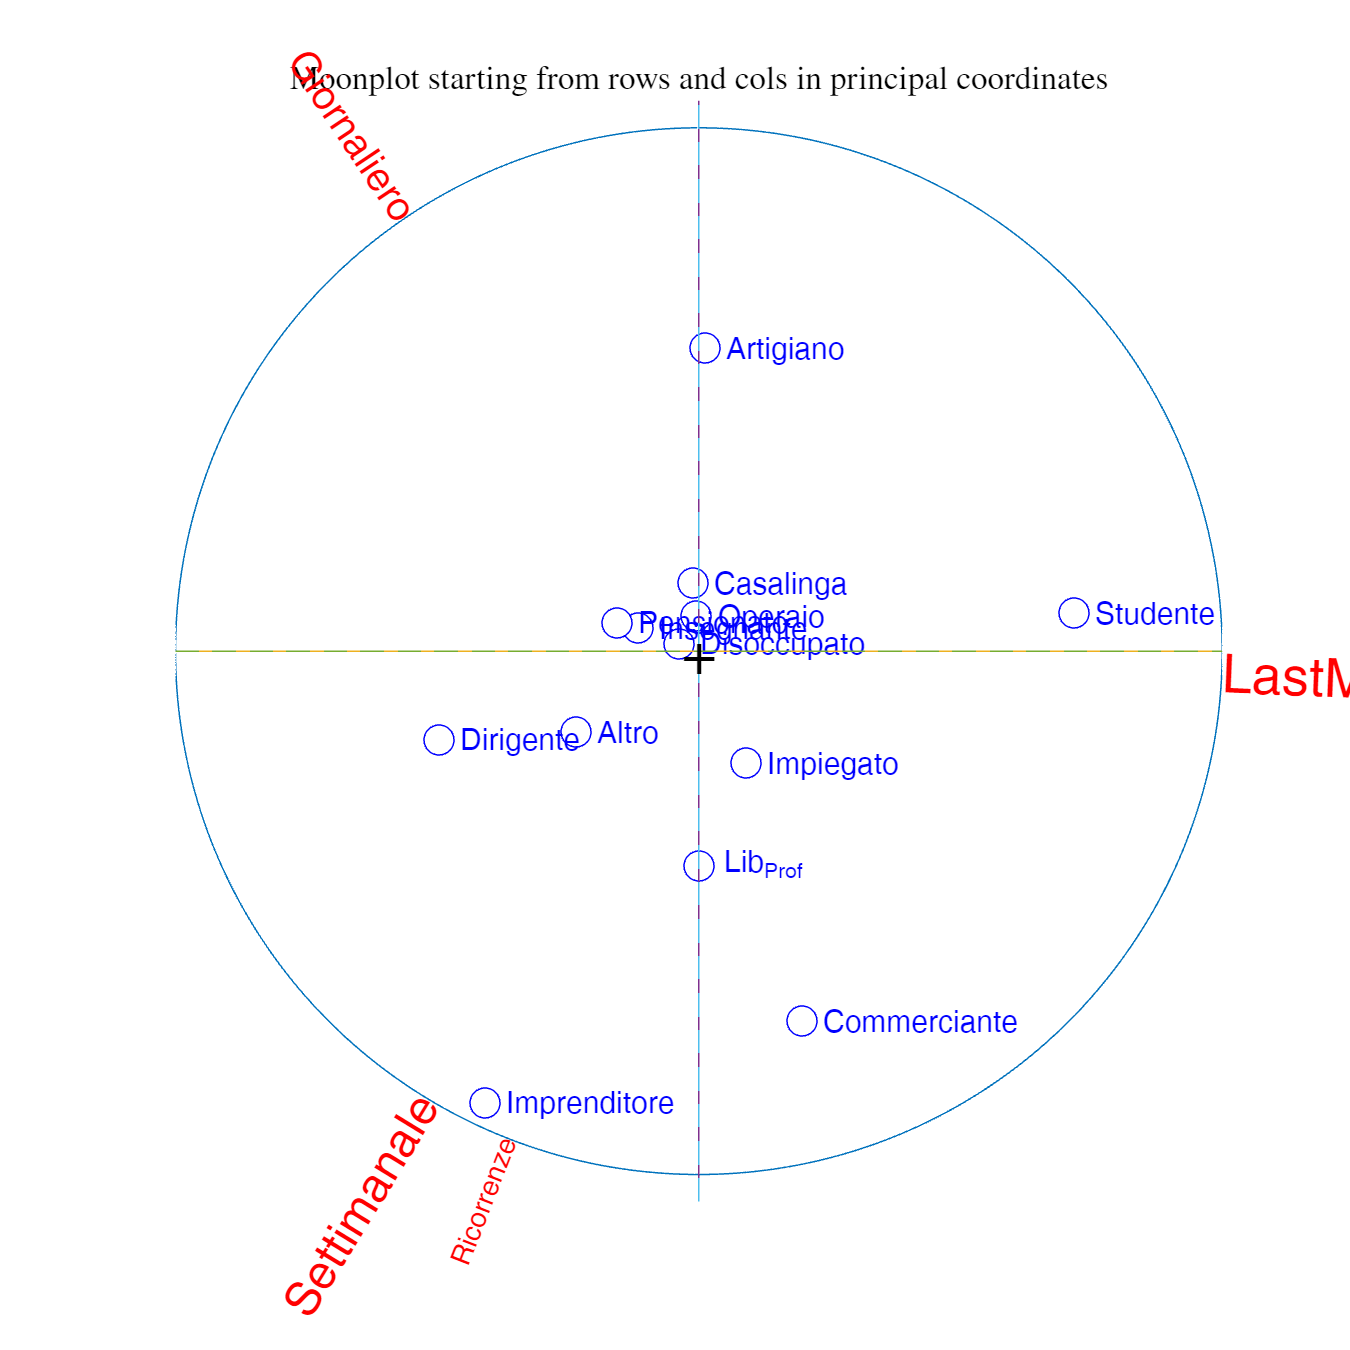

%% Analisi tramite moonplot
% Questo grafico mette chiaramente in evidenza che gli imprenditori sono collocati nella direzione
% di acquisti settimanali (e ricorrenze). La diversa dimensione delle etichette
% Settimanale e Ricorrenze nel moonplot ribadisce che il profilo
% imprenditore è distante dall'origine e ricorrenze è molto più vicino all'origine.
moonplot(out)